robot_name = 'kukaIiwa7';
robot = loadrobot(robot_name, 'DataFormat', 'column');

Loading **KukaIiwa7** Robot

numJoints = numel(homeConfiguration(robot));
endEffector = 'iiwa_link_ee_kuka';

taskInit = trvec2tform([[0.4 0 0.2]])*axang2tform([0 1 0 pi]);
ik = inverseKinematics('RigidBodyTree', robot);
ik.SolverParameters.AllowRandomRestart = false;
weights = [1 1 1 1 1 1];

currentRobotJConfig = ik(endEffector, taskInit, weights, robot.homeConfiguration);
currentRobotJConfig = wrapToPi(currentRobotJConfig);

taskFinal = trvec2tform([0.35 0.55 0.35])*axang2tform([0 1 0 pi]);  
anglesFinal = rotm2eul(taskFinal(1:3,1:3),'XYZ');
poseFinal = [taskFinal(1:3,4);anglesFinal'];

finalRobotJConfig = ik(endEffector, taskFinal, weights, currentRobotJConfig);
finalRobotJConfig = wrapToPi(finalRobotJConfig);

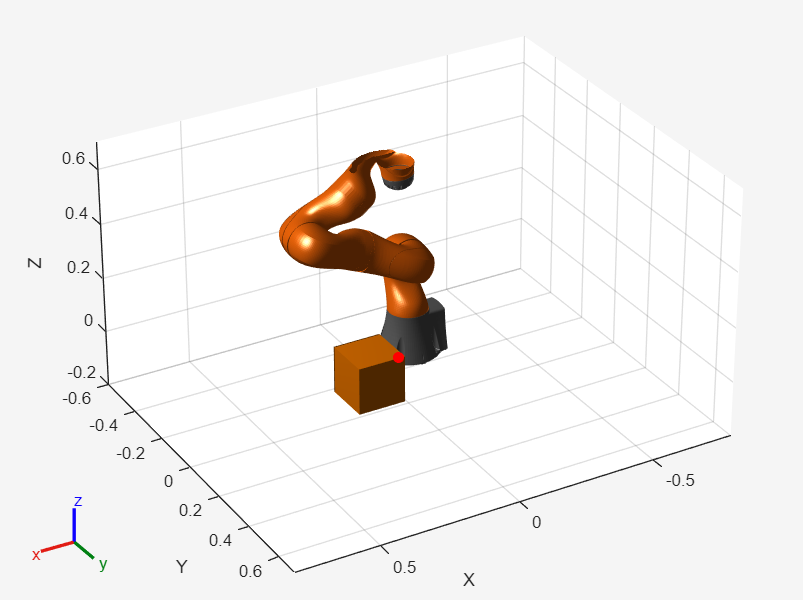

addpath('../Task1');
helperCreateObstaclesKINOVA;
x0 = [currentRobotJConfig', zeros(1,numJoints)];
helperInitialVisualizerKINOVA;

safetyDistance = 0.01; 

Elapsed time is 1.696348 seconds.


Qtheta = 19.1523

RAR = 10.5537

Elapsed time is 1.628986 seconds.


Qtheta = 19.2277

RAR = 10.5537

STOMP Finished.


isTrajectoryInCollision = logical
   1


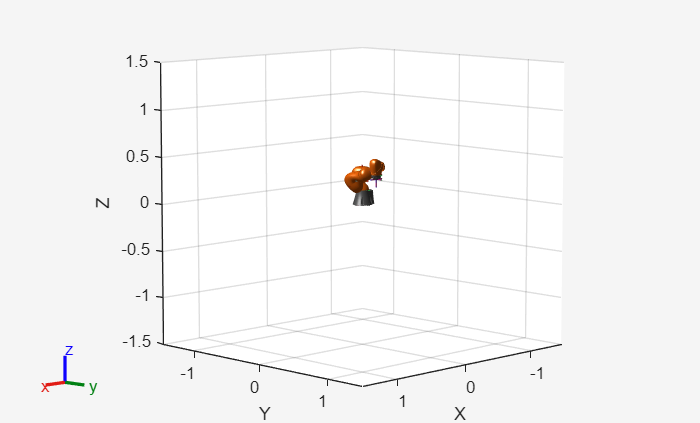

helperSTOMP;